% Scenario Setup (Crucial: Use UTC timezone)
startTime = datetime('now', 'TimeZone','UTC'); % Or your specific UTC time
stopTime = startTime + days(2); % 2-day simulation
sampleTime = 10; % Seconds
sc = satelliteScenario(startTime, stopTime, sampleTime);

% Load TLE Files (ensure files exist in working directory)
debrisTLE = 'D:\Anirudh\Academics\Engineering\2nd Year\4th sem\MS Lab\project\debris.tle'; % Verify exact filename
sat1TLE = 'D:\Anirudh\Academics\Engineering\2nd Year\4th sem\MS Lab\project\satellite1.tle'; 
sat2TLE = "D:\Anirudh\Academics\Engineering\2nd Year\4th sem\MS Lab\project\satellite2.tle";

% Add Satellites with proper propagators
satDebris = satellite(sc, debrisTLE, 'OrbitPropagator', 'sgp4');
satActive1 = satellite(sc, sat1TLE, 'OrbitPropagator', 'sgp4');
satActive2 = satellite(sc, sat2TLE, 'OrbitPropagator', 'sgp4');

% Verification step
if isempty(satDebris) || isempty(satActive1) || isempty(satActive2)
    error('TLE loading failed. Verify file paths and content.');
end

% Consolidated state retrieval (meters)
[posDebris, ~, time] = states(satDebris); % Direct meter units
posActive1 = states(satActive1);
posActive2 = states(satActive2);

% Vectorized distance calculation (no unit conversions)
dist1 = vecnorm(posActive1 - posDebris, 2, 1)'; % Correct dimension handling [3][5]
dist2 = vecnorm(posActive2 - posDebris, 2, 1)';

% Collision Detection (threshold: 100 meters)
collisionThreshold = 4500; 
[collisionTimes1, collisionIdx1] = getCollisions(time, dist1, collisionThreshold);
[collisionTimes2, collisionIdx2] = getCollisions(time, dist2, collisionThreshold);

% Proximity table generation (preallocated)
proximityTable = preallocateProximityTable();
if ~isempty(collisionIdx1)
    proximityTable = [proximityTable; 
        getProximityData(time, posActive1, posDebris, dist1, collisionIdx1, 'ActiveSat1')];
end
if ~isempty(collisionIdx2)
    proximityTable = [proximityTable; 
        getProximityData(time, posActive2, posDebris, dist2, collisionIdx2, 'ActiveSat2')];
end

% Display Results
fprintf('Minimum Distance to Debris:\nActiveSat1: %.2f m\nActiveSat2: %.2f m\n\n',...
    min(dist1), min(dist2));

Minimum Distance to Debris:
ActiveSat1: 62748.68 m
ActiveSat2: 747172.84 m




if ~isempty(proximityTable)
    disp('Collision Proximity Data (10 points before/after):');
    disp(proximityTable);
else
    disp('No collisions detected');
end

No collisions detected


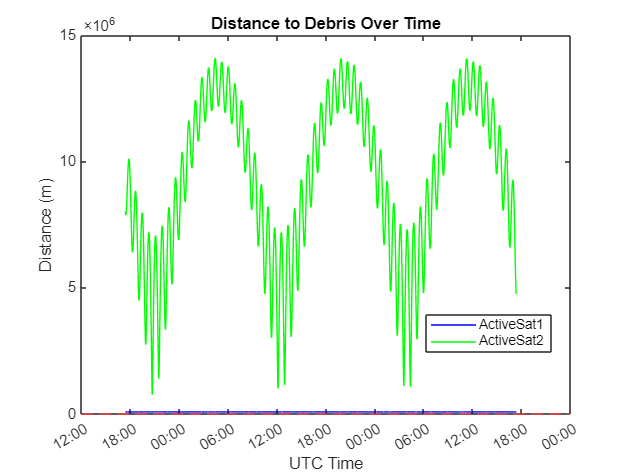


% Enhanced Visualization
plotDistanceProfile(time, dist1, dist2, collisionThreshold);

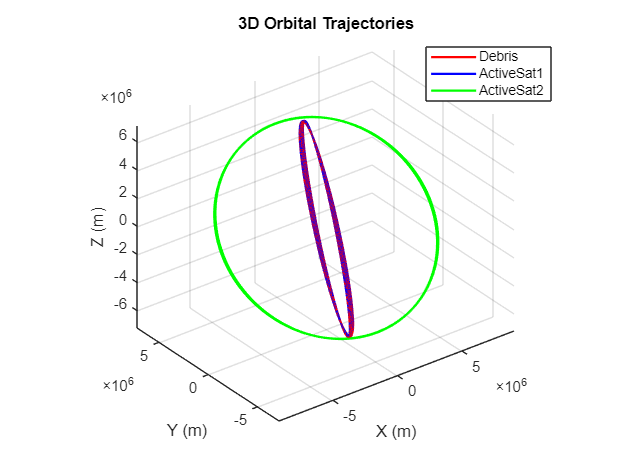

plot3DTrajectories(posDebris, posActive1, posActive2, collisionIdx1, collisionIdx2);

% --- Real-Time 3D Visualization ---
viewer = satelliteScenarioViewer(sc); % Launches the interactive 3D viewer

% Optional: Customize colors and labels
satDebris.MarkerColor = [0.8 0.1 0.1]; % reddish for debris
satActive1.MarkerColor = [0.1 0.1 0.8]; % blue
satActive2.MarkerColor = [0.1 0.8 0.1]; % green

satDebris.Orbit.LineColor = [0.8 0.1 0.1];
satActive1.Orbit.LineColor = [0.1 0.1 0.8];
satActive2.Orbit.LineColor = [0.1 0.8 0.1];

satDebris.LabelFontColor = [0.8 0.1 0.1];
satActive1.LabelFontColor = [0.1 0.1 0.8];
satActive2.LabelFontColor = [0.1 0.8 0.1];

% --- Animate the scenario in real time ---
play(sc); % This lets you watch the satellites move in the viewer

% --- (Optional) Set camera to follow a satellite ---
camtarget(viewer, satActive1); % Camera follows ActiveSat1

%% Helper Functions (Optimized)
function [times, idx] = getCollisions(timeVec, distances, threshold)
    idx = find(distances <= threshold);
    times = timeVec(idx);
end

function tableData = getProximityData(timeVec, satPos, debrisPos, distances, collisions, satName)
    if isempty(timeVec.TimeZone)
        timeVec.TimeZone = 'UTC';
    end

    windowSize = 5; % 10-point window (5 before/after)
    numPoints = numel(collisions)*(2*windowSize +1);
    prealloc = cell(numPoints, 6);
    
    row = 1;
    for i = 1:numel(collisions)
        idx = collisions(i);
        startIdx = max(1, idx-windowSize);
        endIdx = min(numel(timeVec), idx+windowSize);
        idxRange = startIdx:endIdx;
        
        relPos = (satPos(:,idxRange) - debrisPos(:,idxRange))';
        
        for j = 1:length(idxRange)
            prealloc(row,:) = {timeVec(idxRange(j)), relPos(j,1), relPos(j,2), ...
                relPos(j,3), distances(idxRange(j)), satName};
            row = row + 1;
        end
    end
    tableData = cell2table(prealloc(1:row-1,:),...
        'VariableNames',{'Time','X','Y','Z','Distance','Satellite'});
    % Ensure output table uses UTC
    tableData.Time.TimeZone = 'UTC';
end

function tbl = preallocateProximityTable()
    tbl = table('Size',[0 6], 'VariableTypes',...
        {'datetime','double','double','double','double','string'},...
        'VariableNames',{'Time','X','Y','Z','Distance','Satellite'});
    tbl.Time.TimeZone = 'UTC'; 
end

function plotDistanceProfile(time, dist1, dist2, threshold)
    figure;
    plot(time, dist1, 'b', time, dist2, 'g');
    hold on;
    yline(threshold, '--r', 'Collision Threshold', 'LabelVerticalAlignment','bottom');
    title('Distance to Debris Over Time');
    xlabel('UTC Time'); 
    ylabel('Distance (m)');
    legend('ActiveSat1', 'ActiveSat2', 'Location','best');
    datetick('x','keeplimits');
end

function plot3DTrajectories(debrisPos, pos1, pos2, idx1, idx2)
    figure;
    hold on; axis equal; grid on;
    plot3(debrisPos(1,:), debrisPos(2,:), debrisPos(3,:), 'r', 'DisplayName', 'Debris', 'LineWidth', 1.5);
    plot3(pos1(1,:), pos1(2,:), pos1(3,:), 'b', 'DisplayName', 'ActiveSat1', 'LineWidth', 1.5);
    plot3(pos2(1,:), pos2(2,:), pos2(3,:), 'g', 'DisplayName', 'ActiveSat2', 'LineWidth', 1.5);

    % Only plot collision points if needed, and use scatter3 for clarity
    if ~isempty(idx1)
        scatter3(pos1(1,idx1), pos1(2,idx1), pos1(3,idx1), 30, 'k', 'filled', 'DisplayName', 'Collision');
    end
    if ~isempty(idx2)
        scatter3(pos2(1,idx2), pos2(2,idx2), pos2(3,idx2), 30, 'k', 'filled', 'HandleVisibility', 'off');
    end

    title('3D Orbital Trajectories');
    xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
    legend('Location','best');
    view(3);
    rotate3d on;
end


